Use **matlab** to create a data set "dataitems" of 9 items in 3 dimensions for clustering by first setting the random number seed with the commands

**rng(31416)**

**k=0.25;**

**c=1-eye(3);**

**dataitems=[] ;**

**for k=1:3**

**for j=1:3**

**dataitems=[dataitems ; c(k,:)+.k*randn(1,3)];**

**end**

**end**

(a) Use Matlab to create a dendrogram of the items.  

rng(31416)
kk=0.25; % FIXED
c=1-eye(3);
dataitems=[] ;
for k=1:3
    for j=1:3
        dataitems=[dataitems ; c(k,:)+kk*randn(1,3)]; % FIXED
    end
end
dataitems

dataitems =       0.38512      0.71762       1.2654
     -0.29212      0.67223      0.67008
     -0.01742      0.87191       1.4564
       1.3046    -0.087908      0.93085
       1.0213    -0.038994      0.97441
      0.81023      0.34245       1.0137
       0.7874       1.0056     0.033563
       1.2779       1.1996      0.26674
        1.136      0.57687     -0.18506


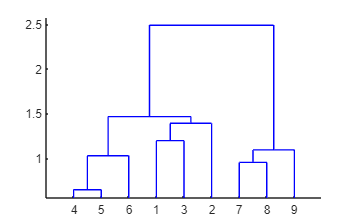

d = pdist(dataitems);
m = squareform(d);
ml = linkage(m);
dendrogram(ml)

(b) Identify three clusters according to the labels (1-9) on the leaves of the tree.

Cluster 1: [1,2,3] 

Cluster 2: [4,5,6]

Cluster 3: [7,8,9]

cluster(ml, 'maxclust', 3)

ans =      2
     2
     2
     1
     1
     1
     3
     3
     3


(c) Generate a new dataset of items using the same random number seed (31416) but a different value of **k** so that the clusters are more well-defined as clusters (tighter).  Compare the dendrograms.

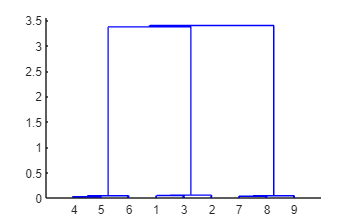

rng(31416)
k2=0.01;
c=1-eye(3);
dataitems=[] ;
for k=1:3
    for j=1:3
        dataitems=[dataitems ; c(k,:)+k2*randn(1,3)];
    end
end
d = pdist(dataitems);
m = squareform(d);
ml = linkage(m);
dendrogram(ml)